## 2.3 Section for evaluation

Consider a toy manufacturing company producing a given toy. The toy is composed by two components (1 and 2) that are produced separately and then are assembled together. At the end, the toys are packed for commercialization in boxes of n toys each. The manufacturing process of Component 1 produces p1 = 0.2% of defective components. The manufacturing process of Component 2 produces p2 = 0.5% of defective components. A toy is defective if at least one of its components is defective. The assembly process produces pa = 1% of defective toys (even when none of the 2 components is defective).

### 1. (Evaluation weight = 20%) Consider the event “A – a box of toys has at least 1 defective toy”.

#### (a) Estimate by simulation the probability of event A when n = 8 toys.

N=1e5;                                                  % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito
nbrinquedos = sum(defeitos);                            % numero de brinquedos com defeito por caixa
caixas = nbrinquedos >=1;                               % soma das caixas com pelo menos um brinquedo com defeito
probA= sum(caixas)/N                                    % calculo da probabilidade do acontecimento A

probA = 0.1280

#### (b) Estimate by simulation the average number of toys that are defective only due to the assembly process when event A occurs and n = 8 toys.

medias = 0;                                             % definir média para somar médias e veer valor médio das experiencias
counter = 0;                                            % definir counter para contar caixas com pelo menos 1 defeito
N=1e5;                                                  % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito  
todosdef = sum(defeitos);                               % soma de todos os brinquedos defeitoosos por caixa 
mdefeitos = (p1+p2)>0;                                  % calculo de defeitos provocados por peças 
mdefeitos = (mdefeitos ~= pa) & pa;                     % calculo de defeitos provocados só por montagem
nmdefeitos = sum(mdefeitos);                            % numero de brinquedos com o defeito só de montagem
for d = 1:N                                             % for para iteração das matrizes
    if(todosdef(d) ~=0)                                 % verificação se existe pelo menos 1 brinquedo com defeito por caixa
        medias= medias + nmdefeitos(d)/todosdef(d);     % soma das médias de brinquedos defeitoosos devido a montagem em comparação aos defeitos totais por caixa
        counter = counter + 1;                          % contador de casos com pelo menos um defeito por caixa
    end                                                 % 
end                                                     %
result = medias/counter                                 % média final das médias obtidas

result = 0.5936

### 2. (Evaluation weight = 30%) Consider the event “B – a box of toys has no defective toys”.

#### (a) Estimate by simulation the probability of event B when n = 8 toys. 

N=1e5;                                                  % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito
nbrinquedos = sum(defeitos);                            % numero de brinquedos com defeito
caixas = nbrinquedos ==0;                               % soma das caixas com nenhum brinquedo com nenhum defeito
probB= sum(caixas)/N                                    % calculo da probabilidade do acontecimento B

probB = 0.8709

#### Check the consistency of this result with the one obtained in question 1(a).

vrfy = probB + probA                                    % verificação se os valores da probA e probB são compativeis

vrfy = 0.9989

#### (b) Determine the theoretical value of the probability of event B and compare it with the value estimated by simulation in question 2(a). 

X = 8;                                                  % (numero de sucessos em n experiências) numero de vezes que um acontecimento A ocorre em
n = 8;                                                  % n experiências de Bernoulli
k = X;                                                  % Pr(X=k)
p1 = 0.002;                                             % probabilidade das peças p1 terem defeito
p2 = 0.005;                                             % probabilidade das peças p2 terem defeito
pa = 0.01;                                              % probabilidade da montagem ter defeito
p = ((1-p1)*(1-p2)*(1-pa));                             % probabilidade do brinquedo não ter defeito, devido a ser sem defeito quer-se-á a probabilidade ~p1 e ~p2 e ~pa, sendo estes acontecimentos independentes tem-se então k a probabilidade destes acontecimentos acontecerem é igual à multiplicação destes 
probtheo = nchoosek(n,k)*p^k*(1-p)^(n-k)                % probabilidade teórica = nchoosek(n,k)*p^k*(1-p)^(n-k) em que nchoosek(n,k)= n!/(n-k)!/k!

probtheo = 0.8724

#### What do you conclude?

probB   

probB = 0.8709

probtheo

probtheo = 0.8724

Pode-se concluir assim que as probabilidades obtidas por simulação e teoricamente são bastante próximas

#### (c) Make the necessary simulations to draw a plot graph of the probability of event B as a function of the box capacity n. Consider all values of n from 2 to 20. 

y = (2:20);                                              % probabilidade do acontecimento B em função da capacidade da caixa
for k =  2:20                                            % (numero de sucessos em n experiências) numero de vezes que um acontecimento A ocorre em n experiências de Bernoulli de 2 a 20
    n =  k;                                              % n experiências de Bernoulli
    p1 = 0.002;                                          % probabilidade das peças p1 terem defeito
    p2 = 0.005;                                          % probabilidade das peças p2 terem defeito
    pa = 0.01;                                           % probabilidade da montagem ter defeito
    p = ((1-p1)*(1-p2)*(1-pa));                          % probabilidade do brinquedo não ter defeito, devido a ser sem defeito quer-se-á a probabilidade ~p1 e ~p2 e ~pa, sendo estes acontecimentos independentes tem-se então k a probabilidade destes acontecimentos acontecerem é igual à multiplicação destes 
    y(k-1) = nchoosek(n,k)*p^k*(1-p)^(n-k);              % y = probabilidade teórica = nchoosek(n,k)*p^k*(1-p)^(n-k) em que nchoosek(n,k)= n!/(n-k)!/k!
end
hold on;
plot(2:20,y,"r.-");
plot(2:20,ones(19)*0.9,"k--");
xlabel ("Capacidade da caixa");
ylabel ("Probabilidade de B");
legend ("Probabilidade de B como funçãos da capacidade da caixa n","Probabilidade de 90%");

#### Describe and justify the obtained results.

#### (d) Analysing the plot drawn in the previous question 2(c), what must be the maximum box capacity if the company wants to guarantee that the probability of each box having no defective toys is at least 90%? 

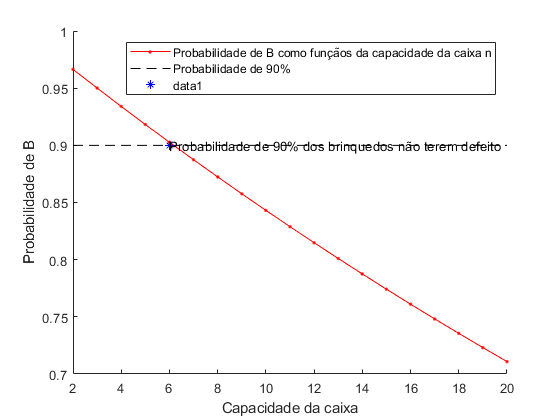

plot(6,0.9,'b*');
text(6,0.9,"Probabilidade de 90% dos brinquedos não terem defeito")
hold off;

### 3. (Evaluation weight = 30%) Consider the random variable X representing the number of defective toys in a box.

#### (a) Estimate by simulation the mass probability function pX(x) of X when n = 8 toys and draw it in a stem graph. 

N = 1e5;                                                % numero de experiencias
n = 8;                                                  % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito
nbrinquedos = sum(defeitos);                            % numero de brinquedos com defeito
xi = (0:8);                                             % conjunto dos valores possiveis de serem assumidos  
px = zeros(1,9);                                        % probabilidade associada a cada um dos valores possiveis de serem assumidos
for val = nbrinquedos                                   % iteração pelos valores obtidos por simulação 
    switch(val)                                         % filtração dos valores
    case 0                                              % caso a caixa tenha 0 brinquedos com defeito              
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 0 brinquedos com defeito
    case 1                                              % caso a caixa tenha 1 brinquedo com defeito                                                                               
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 1 brinquedo com defeito
    case 2                                              % caso a caixa tenha 2 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 2 brinquedos com defeito
    case 3                                              % caso a caixa tenha 3 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 3 brinquedos com defeito
    case 4                                              % caso a caixa tenha 4 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 4 brinquedos com defeito
    case 5                                              % caso a caixa tenha 5 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 5 brinquedos com defeito
    case 6                                              % caso a caixa tenha 6 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 6 brinquedos com defeito
    case 7                                              % caso a caixa tenha 7 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 7 brinquedos com defeito
    case 8                                              % caso a caixa tenha 8 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 8 brinquedos com defeito
    otherwise                                           % verificação de erro
        fprintf("Ocorreu um erro\n");                   % aviso de erro
    end                                                 % 
end                                                     %
px = px/(N)                                             % cálculo da probabilidade associada a cada um dos valores possiveis de serem assumidos

px =     0.8731    0.1190    0.0075    0.0004    0.0000         0         0         0         0


sum(px)                                                 % verificação de resultados (soma tem que ser igual a 1)

ans = 1

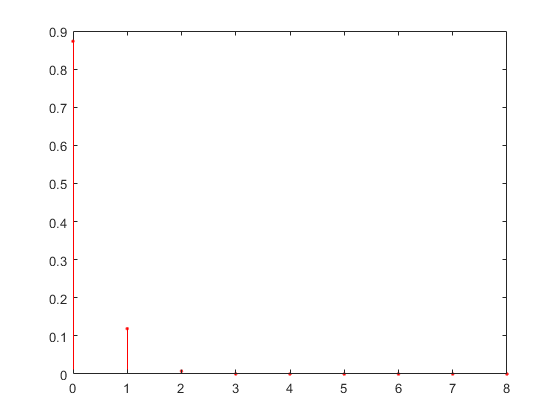

stem(xi,px,"filled",'r.')                               % stem da função massa

#### Describe the obtained results and check their consistency with the result obtained in question 2(a).

probB                                                   % probabilidade de não existirem brinquedos defeitoosos numa caixa com n brinquedos

probB = 0.8709

px(1)                                                   % probabilidade obtida por simulação de não existirem brinquedos defeitoosos numa caixa com n brinquedos

ans = 0.8731

#### (b) Based on pX(x), compute the probability of X >= 2. 

px2 = sum(px(3:9));                                     % probabilidade obtida por simulação de existirem >= 2 brinquedos defeitoosos numa caixa com n brinquedos, soma das probabilidades de sairem 2 a 8 brinquedos defeitoosos por caixa com n brinquedos
px2                                                     % observação do resultado

px2 = 0.0079

#### What do you conclude?

#### (c) Based on pX(x), estimate the expected value, variance and standard deviation of X.

#### Expected value

E = sum(xi .* px)                                       % valor esperado, tem-se que o valor esperado seja igual ao somatório de xi*p(xi)

E = 0.1352

E                                                       % observação do valor esperado

E = 0.1352

#### Variance

var = sum((xi - E) .^2 .* px)                           % variancia, tem-se que o valor da variancia seja igual ao somatório de ((xi-E(X))^2)*p(xi) 

var = 0.1342

var                                                     % observação da variancia

var = 0.1342

#### Standard deviation

devi = sqrt(var);                                       % desvio padrão, este é calculado fazendo a raiz quadrada da variancia
devi                                                    % observação do desvio padrão

devi = 0.3664

### (d) Repeat questions 3(a), 3(b) and 3(c) but now considering n = 16 toys. Compare all results with the previous ones (obtained with n = 8 toys) and justify the differences.

#### (a) Estimate by simulation the mass probability function pX(x) of X when n = 16 toys and draw it in a stem graph. 

N = 1e5;                                                % numero de experiencias
n = 16;                                                 % numero de brinquedos por caixa
experiencias = rand(n,N);                               % fabrico de peças p1
p1  = experiencias < 0.002;                             % peças p1 com defeito
experiencias = rand(n,N);                               % fabrico de peças p2
p2  = experiencias < 0.005;                             % peças p2 com defeito
experiencias = rand(n,N);                               % processo de montagem pa
pa  = experiencias < 0.01;                              % defeitos na montagem pa com defeito
ndefeitos = p1 + p2 + pa;                               % numero de defeitos por brinquedo
defeitos = ndefeitos > 0;                               % brinquedos com defeito
nbrinquedos = sum(defeitos);                            % numero de brinquedos com defeito
xi = (0:8);                                             % conjunto dos valores possiveis de serem assumidos  
px = zeros(1,9);                                        % probabilidade associada a cada um dos valores possiveis de serem assumidos
for val = nbrinquedos                                   % iteração pelos valores obtidos por simulação 
    switch(val)                                         % filtração dos valores
    case 0                                              % caso a caixa tenha 0 brinquedos com defeito              
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 0 brinquedos com defeito
    case 1                                              % caso a caixa tenha 1 brinquedo com defeito                                                                               
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 1 brinquedo com defeito
    case 2                                              % caso a caixa tenha 2 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 2 brinquedos com defeito
    case 3                                              % caso a caixa tenha 3 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 3 brinquedos com defeito
    case 4                                              % caso a caixa tenha 4 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 4 brinquedos com defeito
    case 5                                              % caso a caixa tenha 5 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 5 brinquedos com defeito
    case 6                                              % caso a caixa tenha 6 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 6 brinquedos com defeito
    case 7                                              % caso a caixa tenha 7 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 7 brinquedos com defeito
    case 8                                              % caso a caixa tenha 8 brinquedos com defeito
        px(val+1) = px(val+1) + 1;                      % contar numero de caixas com 8 brinquedos com defeito
    otherwise                                           % verificação de erro
        fprintf("Ocorreu um erro\n");                   % aviso de erro
    end                                                 % 
end                                                     %
px = px/(N)                                             % cálculo da probabilidade associada a cada um dos valores possiveis de serem assumidos

px =     0.7593    0.2111    0.0275    0.0020    0.0001         0         0         0         0


sum(px)                                                 % verificação de resultados (soma tem que ser igual a 1)

ans = 1

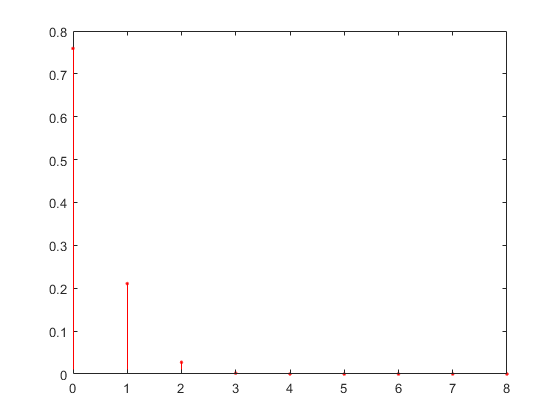

stem(xi,px,"filled",'r.')                               % stem da função massa

px(1)                                                   % probabilidade obtida por simulação de não existirem brinquedos defeitoosos numa caixa com n brinquedos

ans = 0.7594

#### (b) Based on pX(x), compute the probability of X >= 2. 

px2 = 0;                                                % probabilidade obtida por simulação de existirem >= 2 brinquedos defeitoosos numa caixa com n brinquedos
for i = 3:9                                             % iteração das probabilidades de sairem 2 a 8 brinquedos defeitoosos por caixa com n brinquedos
    px2 = px2 + px(i);                                  % soma das probabilidades de sairem 2 a 8 brinquedos defeitoosos por caixa com n brinquedos
end                                                     %
px2                                                     % observação do resultado

px2 = 0.0296

#### What do you conclude?

#### (c) Based on pX(x), estimate the expected value, variance and standard deviation of X.

#### Expected value

E = sum(xi .* px)                                       % valor esperado, tem-se que o valor esperado seja igual ao somatório de xi*p(xi)

E = 0.2725

E                                                       % observação do valor esperado

E = 0.2725

#### Variance

var = sum((xi - E) .^2 .* px)                           % variancia, tem-se que o valor da variancia seja igual ao somatório de ((xi-E(X))^2)*p(xi) 

var = 0.2667

var                                                     % observação da variancia

var = 0.2667

#### Standard deviation

devi = sqrt(var);                                       % desvio padrão, este é calculado fazendo a raiz quadrada da variancia
devi                                                    % observação do desvio padrão

devi = 0.5164

### 4. (Evaluation weight = 20%) Assume now that the company aims to commercialize the toys in boxes of n = 20 toys guaranteeing that the probability of commercializing a box without defective toys is at least 90%. 

### To reach this goal, the assembly process was improved by reducing pa to 0.1% and a quality assurance process was implemented as follow: a sample of m toys (with 1 ≤ m < 20) is selected from each box for testing; the box is not commercialized if at least one of the selected toys is defective or is commercialized, otherwise.

#### (a) Estimate by simulation the probability of a box being commercialized when the quality assurance process is set with m = 1 (check the usefulness of Matlab function randperm in the implementation of the simulation). 

#### What do you conclude?

#### (b) Estimate by simulation the lowest value of m that is required to reach the desired goal.